d_W =                    0
   8.429391771891961
  13.630186840403104
  16.354901271449734
  17.180654272567917
  16.550040001610189
  14.802711087683569
  12.197914267762542
   8.929693279054344
   5.306372144605683


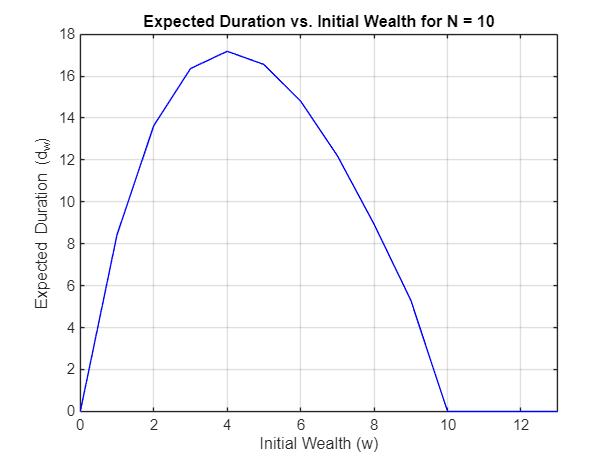

d_W = 1.0e+02 *

                   0
   0.580606504615950
   1.013247372317063
   1.332410175129995
   1.564544182073401
   1.729933912773082
   1.844136006475269
   1.919081188141743
   1.963919390213603
   1.985667894871527


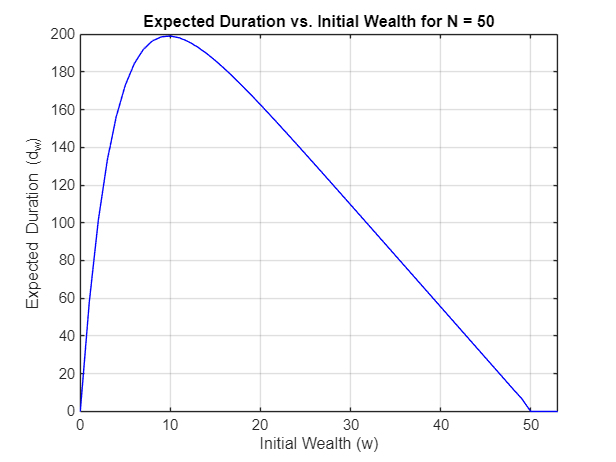

d_W = 1.0e+02 *

                   0
   1.212549846916557
   2.129841807252885
   2.820694073139193
   3.337884812769589
   3.721890751145143
   4.003754368951942
   4.207282819736127
   4.350734327307231
   4.448111520582378


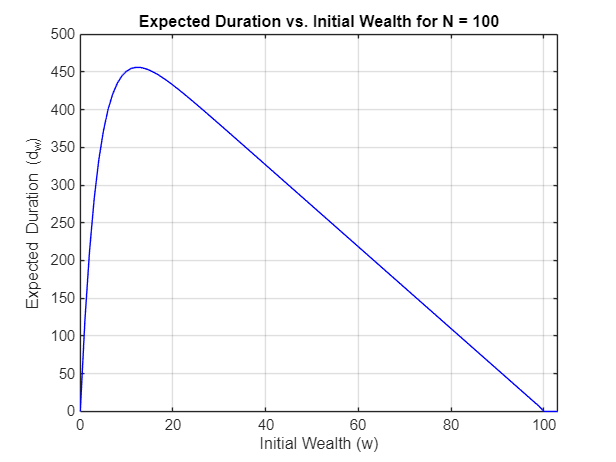

format long

N_values = [10, 50, 100]; 
n = length(N_values); 
p_4 = 1/1296;
p_3 = 5/324;
p_2 = 25/216;
p_1 = 125/324;
q = 625/1296;
 

for i = 1:n
    N = N_values(i);

P = zeros(N+4, N+4);  

P(1,1) = 1;
P(N+1,N+1) = 1;
P(N+2,N+2) = 1; 
P(N+3,N+3) = 1; 
P(N+4,N+4) = 1; 

for row = 2:N
    P(row, row-1) = q; 
    P(row, row) = 0;
    P(row, row+1) = p_1;
    P(row, row+2) = p_2;
    P(row, row+3) = p_3;
    P(row, row+4) = p_4;
end

% Extract Q and R matrices
Q = P(2:N, 2:N);        % Transient-to-transient transitions
R = [P(2:N, 1), P(2:N, N+1), P(2:N, N+2), P(2:N, N+3), P(2:N, N+4)];  % Transient-to-absorbing transitions

% Fundamental matrix
I = eye(size(Q));
F = inv(I - Q);
m = length(F(:,1));
c = ones (m, 1);
D = F*c;
D_full = [0; D; 0; 0; 0; 0];

% Extract ruin probabilities
d_W = double(D_full)
    figure;
    plot(0:N+3, d_W, 'b', 'DisplayName', 'd\_W');
    xlabel('Initial Wealth (w)');
    ylabel('Expected Duration (d_w)');
    title(['Expected Duration vs. Initial Wealth for N = ', num2str(N)]);
    grid on;
    xlim([0 N+3])
end